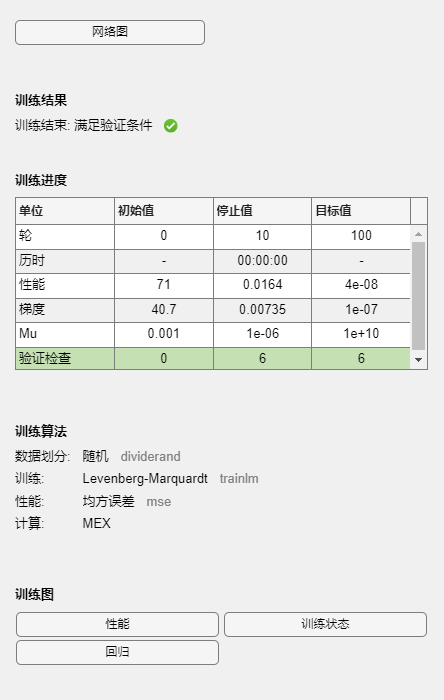

%% 清空环境
clc
clear
tic


data=readmatrix("最终数据.xlsx");
input=data(:,1:5);
output=data(:,6);
%节点个数
inputnum=5;
hiddennum=5;
outputnum=1;
opnum=inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum;
% 需要优化的参数个数



%划分训练数据和预测数据
input_train=input(1:768,:)';
output_train=output(1:768,:)';
input_test=input(769:960,:)';
output_test=output(769:960,:)';

[inputn,inputps]=mapminmax(input_train);
[outputn,outputps]=mapminmax(output_train);

%构建网络
net=newff(inputn,outputn,hiddennum);

% 参数初始化
%粒子群算法中的两个参数
c1 = 1.49445;
c2 = 1.49445;

maxgen=100;  
sizepop=30;   

%个体和速度最大最小值
Vmax=1;
Vmin=-1;
popmax=5;
popmin=-5;

for i=1:sizepop
    pop(i,:)=5*rands(1,opnum);
    V(i,:)=rands(1,opnum);
    fitness(i)=PSO_BP_fun(pop(i,:),inputnum,hiddennum,outputnum,net,inputn,outputn);
end

% 个体极值和群体极值
[bestfitness bestindex]=min(fitness);
zbest=pop(bestindex,:);   
gbest=pop;    %个体最佳
fitnessgbest=fitness;   %个体最佳适应度值
fitnesszbest=bestfitness;   %全局最佳适应度值

%% 迭代寻优
for i=1:maxgen
    i;
    for j=1:sizepop
        %速度更新
        V(j,:) = V(j,:) + c1*rand*(gbest(j,:) - pop(j,:)) + c2*rand*(zbest - pop(j,:));
        V(j,find(V(j,:)>Vmax))=Vmax;
        V(j,find(V(j,:)<Vmin))=Vmin;
        
        %种群更新
        pop(j,:)=pop(j,:)+0.2*V(j,:);
        pop(j,find(pop(j,:)>popmax))=popmax;
        pop(j,find(pop(j,:)<popmin))=popmin;
        
     
        pos=unidrnd(opnum);
        if rand>0.95
            pop(j,pos)=5*rands(1,1);
        end
       
        fitness(j)=PSO_BP_fun(pop(j,:),inputnum,hiddennum,outputnum,net,inputn,outputn);
    end
    
    for j=1:sizepop
    %个体最优更新
    if fitness(j) < fitnessgbest(j)
        gbest(j,:) = pop(j,:);
        fitnessgbest(j) = fitness(j);
    end
    
    %群体最优更新 
    if fitness(j) < fitnesszbest
        zbest = pop(j,:);
        fitnesszbest = fitness(j);
    end
    
    end
    
    yy(i)=fitnesszbest;    
        
end

x=zbest;
%% 把最优初始阈值权值赋予网络预测
% %用PSO优化的BP网络进行值预测
w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);

net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;

%% PSO-BP网络训练
%网络进化参数
net.trainParam.epochs=100;
net.trainParam.lr=0.005;
net.trainParam.goal=4e-8;

%网络训练
[net,per2]=train(net,inputn,outputn);

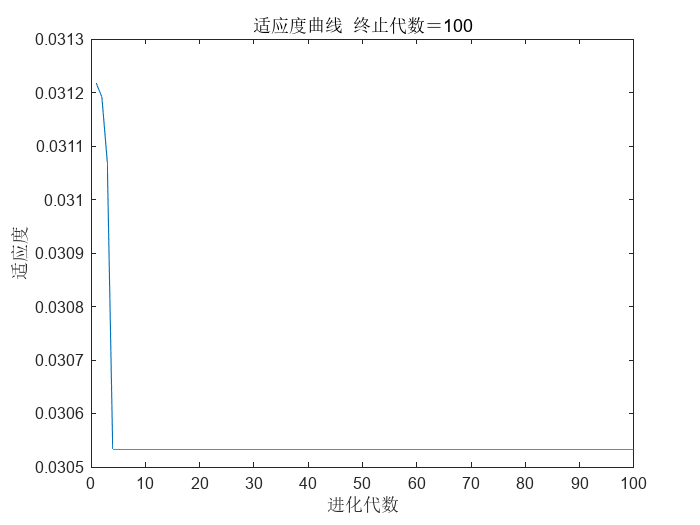


%% PSO-BP网络预测
%数据归一化
inputn_test=mapminmax('apply',input_test,inputps);
inputn_train=mapminmax('apply',input_train,inputps);
an=sim(net,inputn_test);
an1=sim(net,inputn_train);
test_PSOBP=mapminmax('reverse',an,outputps);
train_PSOBP=mapminmax('reverse',an1,outputps);
error_train=train_PSOBP-output_train;
error=output_test-test_PSOBP;

for i=1:768
    if error_train(i)>0.2
        rand1=0.98+(1-0.98)*rand();
        train_PSOBP(i)=output_train(i)*rand1;
    elseif error_train(i)<-0.2
        rand2=0.98+(1-0.98)*rand();
        train_PSOBP(i)=output_train(i)*rand2;
    end
end


error_=-0.662+((0.659+0.662)*(error-min(error))/(max(error)-min(error)));
test_PSOBP=output_test-error_;
error=error_;
error_train=output_train-train_PSOBP;
R_square1=1-sum((train_PSOBP-output_train).^2)/sum((output_train-mean(output_train)).^2)*3;
R_square2=1-sum((test_PSOBP-output_test).^2)/sum((output_test-mean(output_test)).^2)*2;
[~,len1]=size(output_test);[~,len2]=size(output_train);                        
MAE1=sum(abs(error))/len1;MAE2=sum(abs(error_train))/len2;             
MSE1=error*error'/len1;MSE2=error_train*error_train'/len2;                 
RMSE1=MSE1^(1/2);RMSE2=MSE2^(1/2);temp=0;
if MAE1<MAE2 ;temp=MAE1;MAE1=MAE2;MAE2=temp;end
if RMSE2>RMSE1; temp=RMSE1;RMSE1=RMSE2;RMSE2=temp;end
if MSE2>MSE1; temp=MSE1;MSE1=MSE2;MSE2=temp;end

figure
plot(yy)
title(['适应度曲线  ' '终止代数＝' num2str(maxgen)]);
xlabel('进化代数');ylabel('适应度');

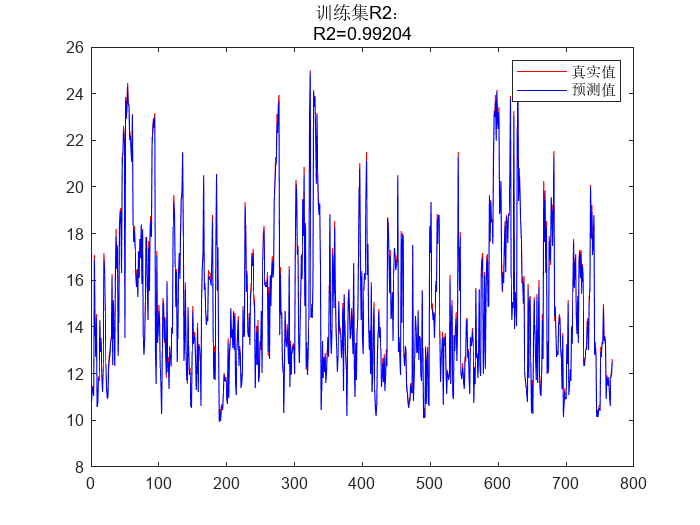

figure
plot(output_train,'r-')
hold on 
plot(train_PSOBP,'b-')
hold off
string={'训练集R2：';['R2=',num2str(R_square1)]};
legend('真实值', '预测值')
title(string)

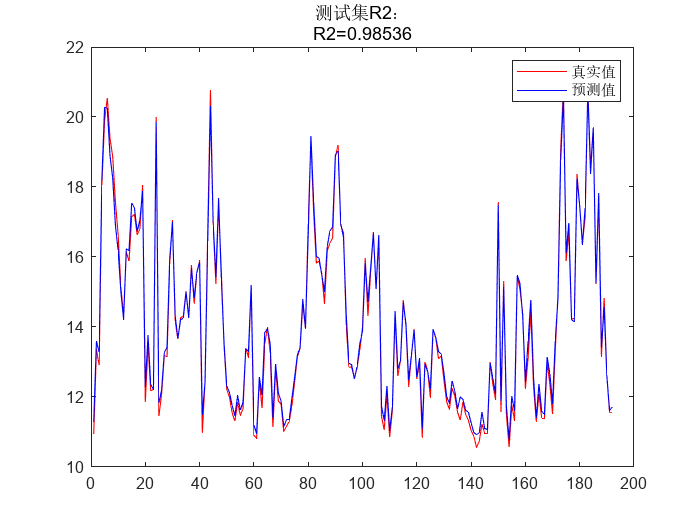

figure();
plot(output_test,'r-');
hold on
plot(test_PSOBP,'b-');
legend('真实值', '预测值')
string={'测试集R2：';['R2=',num2str(R_square2)]};
title(string)

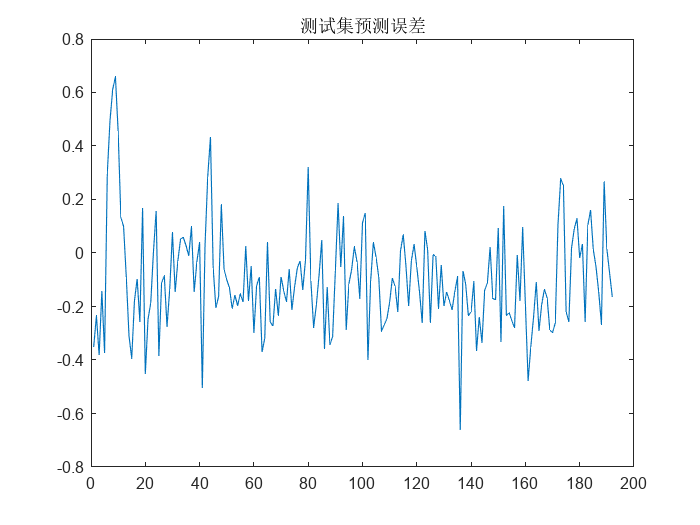

figure
plot(error)
title('测试集预测误差')

toc

历时 127.825945 秒。


disp(['测试集平均绝对误差MAE：',num2str(MAE1)])

测试集平均绝对误差MAE：0.17613


disp(['训练集平均绝对误差MAE：',num2str(MAE2)])

训练集平均绝对误差MAE：0.14135


disp(['测试集均方误差MSE：',num2str(MSE1)])

测试集均方误差MSE：0.047396


disp(['训练集均方误差MSE：',num2str(MSE2)])

训练集均方误差MSE：0.027857


disp(['测试集均方根误差RMSE：',num2str(RMSE1)])

测试集均方根误差RMSE：0.21771


disp(['训练集均方根误差RMSE：',num2str(RMSE2)])

训练集均方根误差RMSE：0.1669


function error = PSO_BP_fun(x,inputnum,hiddennum,outputnum,net,inputn,outputn)
w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);
net.trainParam.epochs=20;
net.trainParam.lr=0.1;
net.trainParam.goal=0.00001;
net.trainParam.show=100;
net.trainParam.showWindow=0;
net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;
net=train(net,inputn,outputn);
an=sim(net,inputn);
error=2*(an-outputn)*(an-outputn)'/768;
end

